# modelBorgifier test 

Load Cobra toolbox. Keep initCobraToolbox(false) because it can start a

long update process

% cd to cobra folder
cd 'C:\Users\kamoo\OneDrive\Desktop\Karlis\MedSysBio\CRC\Worm_models\cobra'

% Keep initCobraToolbox(false) because it can start a long update process

initCobraToolbox(false)


% cd to working directory
cd 'C:\Users\kamoo\OneDrive\Desktop\Karlis\MedSysBio\CRC\Worm_models'

% Worm models

tic
Wormjam = readCbModel('WormJam-GEM.xml')
iCEL_model = readCbModel('iCEL1314.mat')
toc

% Microbe models

tic
myb11 = readCbModel('MYb11.xml')
myb71 = readCbModel('MYb71.xml')
myb115 = readCbModel('MYb115.xml')
toc

% Use COBRAs modelborgifier function
Cmodel = myb11;
Tmodel = iCEL_model;


% Verify model has the necessary fields required for later processing
Cmodel = verifyModelBorg(Cmodel, 'keepName', 'Verbose');

Array .rxnID not in Model. Adding.
Array .rxnSEEDID not in Model. Adding.
Array .rxnEquations not in Model. Adding.
Array .rxnReferences not in Model. Adding.
Array .rxnNotes not in Model. Adding.
Array .grRules not in Model. Adding.
Array .metID not in Model. Adding.
Array .metChEBIID not in Model. Adding.
Array .metPubChemID not in Model. Adding.
Array .metInChIString not in Model. Adding.
Array .metCharge not in Model. Adding.
Making sure reactions are all forwards
Fixing names of metabolites and reaction
Checking if reaction IDs (.rxns) are unique.
Checking if metabolite IDs (.mets) are unique.
Some metabolites have no compartment designation. Assigning as cytosolic.
Sorry, this model name is invalid. (Hint: it must start with a letter and only contain letters and numbers)






% If Tmodel is just another model, verify it as well and convert it to a
% proper format for comparison. Also make sure it carries flux.
Tmodel = verifyModelBorg(Tmodel, 'keepName', 'Verbose');

Array .rxnID not in Model. Adding.
Array .rxnKEGGID not in Model. Adding.
Array .rxnSEEDID not in Model. Adding.
Array .rxnEquations not in Model. Adding.
Array .rxnReferences not in Model. Adding.
Array .rxnNotes not in Model. Adding.
Array .metID not in Model. Adding.
Array .metKEGGID not in Model. Adding.
Array .metSEEDID not in Model. Adding.
Array .metChEBIID not in Model. Adding.
Array .metPubChemID not in Model. Adding.
Array .metInChIString not in Model. Adding.
Array .metCharge not in Model. Adding.
Making sure reactions are all forwards
Fixing names of metabolites and reaction
Checking if reaction IDs (.rxns) are unique.
Checking if metabolite IDs (.mets) are unique.
All metabolites have comparment designation.
Sorry, this model name is invalid. (Hint: it must start with a letter and only contain letters and numbers)



Tmodel = buildTmodel(Tmodel);

Adding comparison information time = 3.930872e+00.
Name match time = 2.639262e+01.
EC match time = 1.081326e+01.
Reaction KEGG ID match time = 1.675598e+00.
Reaction SEED ID match time = 1.382400e-03.
Subsystem match time = 8.227636e+00.
Metabolte number and stoich match time = 1.568334e+00.
Reaction compartment match time = 4.511937e-01.
Network topology match time = 5.846792e+01.


Met name match time = 5.305931e+03.


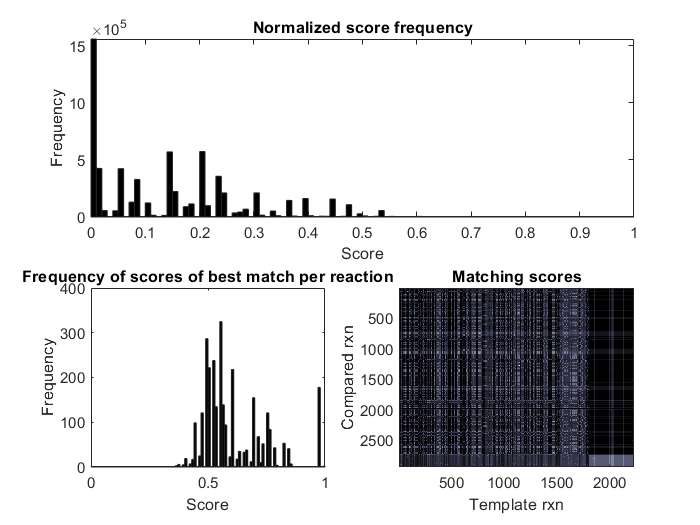

%Compare the models *TAKES VERY LONG*
[Cmodel, Tmodel, score, Stats] = compareCbModels(Cmodel, Tmodel, 'Verbose');